% ==========================================================
% main_generator.m - 主数据生成脚本
% ==========================================================
clear; clc; close all;

% --- 1. 公共参数设置 ---
params.fs = 100e6;       % 采样频率 100MHz
params.fc = 40e6;        % 中心频率 40MHz
params.B = 10e6;         % 带宽    10MHz
params.taup = 10e-6;     % LFM脉宽 10us
params.Np = 16;          % 脉冲个数 16
params.PRI = 200e-6;     % 脉冲重复间隔
params.SNR = 15;         % 信噪比
params.JNR = 15;         % 干信比 (可以为不同干扰类型单独设置)
params.pos = 5000;       %在PRI中第5000点处
JNR_values = 10:5:20;    % 信噪比范围 dB


% --- 2. 生成计划 ---
% 定义要生成的干扰类型和对应的标签
generation_plan = {
    % 欺骗干扰
    'DFTJ', 1, 1;
    % 'ISRJ', 2, 200;
    % 'DDJ' , 3, 200;
    % 'VDJ' , 4, 200;
    % 压制干扰
    % 'AJ'  , 5, 1;
    % 'BJ'  , 6, 1;
    % 'SJ'  , 7, 1;
    % 'NCJ' , 8, 1;
    % 'NPJ' , 9, 1;
    % 在这里添加更多类型，例如 'sweep', 3, 200
    };

% --- 3. 初始化数据容器 ---
all_samples = [];
all_labels = [];

% --- 4. 执行生成 ---
% 生成基础目标信号 (所有干扰类型共用)
[tx, params] = generate_base_signal(params);


## 循环生成每种干扰

len = size(generation_plan, 1)

len = 1

for current_jnr = JNR_values
    % 初始化数据容器
    all_samples = [];
    all_labels = [];
    for i = 1:len
        jam_type = generation_plan{i, 1};
        label = generation_plan{i, 2};
        num_to_generate = generation_plan{i, 3};
        fprintf('正在生成 %d 个 [%s] 类型的样本, 标签为 %d...\n', num_to_generate, jam_type, label);

        Aj = 10^(current_jnr/20);
        % 创建当前SNR值的子文件夹
        snr_output_dir = fullfile('data2501114', sprintf('JNR_%+d', current_jnr));
        if ~exist(snr_output_dir, 'dir')
            mkdir(snr_output_dir);
        end
        fprintf('Generating data for JNR = %d dB...\n', current_jnr);

        switch jam_type
            case 'DFTJ'
                jam_params = params;
                jam_params.JNR = current_jnr; % 瞄准干扰通常功率更集中
                jam_params.BJ = 20e6;         % 干扰带宽 20MHz
                [new_samples, new_labels] = generate_ab_jamming(tx, jam_params, label, num_to_generate);

            case 'AJ'
                jam_params = params;
                jam_params.JNR = current_jnr; % 瞄准干扰通常功率更集中
                jam_params.BJ = 20e6;         % 干扰带宽 20MHz
                [new_samples, new_labels] = generate_ab_jamming(tx, jam_params, label, num_to_generate);

            case 'BJ'
                jam_params = params;
                jam_params.JNR = current_jnr; % 阻塞干扰
                jam_params.BJ = 45e6;         % 干扰带宽 45MHz
                [new_samples, new_labels] = generate_ab_jamming(tx, jam_params, label, num_to_generate);
            case 'SJ'
                jam_params = params;
                jam_params.JNR = current_jnr; % 扫频干扰
                jam_params.BJ = 10e6;          % 干扰带宽 5MHz
                [new_samples, new_labels] = generate_sj_jamming(tx, jam_params, label, num_to_generate);

            case 'NCJ'
                jam_params = params; % 使用公共JNR
                [new_samples, new_labels] = generate_ncj_jamming(tx, jam_params, label, num_to_generate);
            case 'NPJ'
                jam_params = params; % 使用公共JNR
                [new_samples, new_labels] = generate_npj_jamming(tx, jam_params, label, num_to_generate);


        end
    % 追加到总数据集中
    all_samples = [all_samples; new_samples];
    all_labels = [all_labels; new_labels];
    end
    
    all_time = fullfile(snr_output_dir, 'echo_time.mat');
    all_label = fullfile(snr_output_dir, 'echo_label.mat');
    save(all_time, 'all_samples', '-v7.3');
    save(all_label, 'all_labels', '-v7.3');
end

正在生成 1 个 [NCJ] 类型的样本, 标签为 8...


Generating data for JNR = 10 dB...


正在生成 1 个 [NCJ] 类型的样本, 标签为 8...


Generating data for JNR = 15 dB...


正在生成 1 个 [NCJ] 类型的样本, 标签为 8...


Generating data for JNR = 20 dB...


## 绘图

rx = all_samples(1,:)

rx =   -0.0001 - 0.0023i  -0.0011 + 0.0007i   0.0013 - 0.0011i  -0.0006 - 0.0009i  -0.0015 - 0.0004i  -0.0019 - 0.0006i   0.0012 + 0.0001i   0.0006 + 0.0004i   0.0018 - 0.0007i   0.0009 + 0.0002i   0.0006 - 0.0007i  -0.0010 + 0.0010i   0.0016 - 0.0002i  -0.0018 - 0.0014i   0.0016 - 0.0004i  -0.0008 + 0.0012i  -0.0008 - 0.0004i  -0.0013 + 0.0006i   0.0020 + 0.0003i  -0.0002 + 0.0003i   0.0025 + 0.0006i  -0.0017 - 0.0015i   0.0003 - 0.0005i  -0.0006 + 0.0009i   0.0003 - 0.0002i  -0.0015 + 0.0000i   0.0003 + 0.0020i  -0.0015 + 0.0005i  -0.0009 + 0.0007i  -0.0002 - 0.0023i   0.0021 + 0.0013i   0.0006 + 0.0002i  -0.0013 - 0.0014i  -0.0017 + 0.0018i  -0.0001 - 0.0009i   0.0020 - 0.0006i  -0.0005 - 0.0003i  -0.0002 - 0.0017i   0.0001 - 0.0016i  -0.0001 + 0.0025i   0.0017 - 0.0022i   0.0009 - 0.0001i   0.0008 + 0.0013i  -0.0009 - 0.0007i  -0.0020 - 0.0008i   0.0007 + 0.0002i   0.0001 + 0.0008i  -0.0004 - 0.0006i  -0.0003 + 0.0001i  -0.0012 + 0.0012i


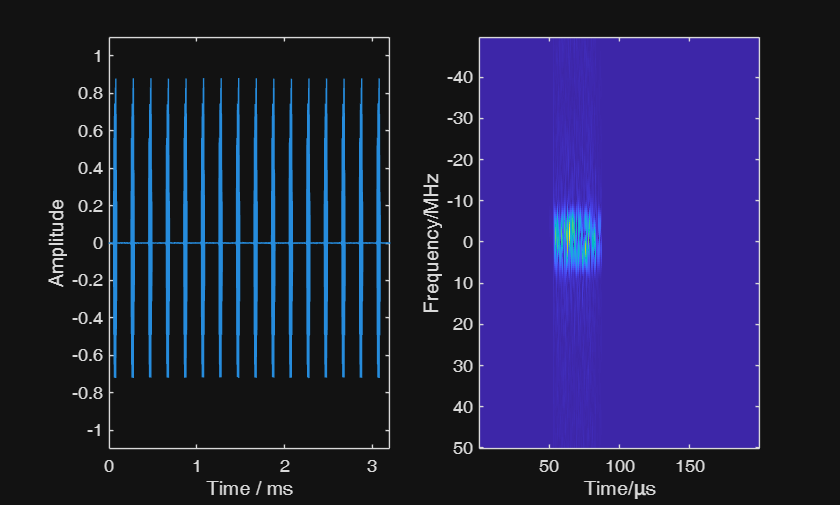

figure;
subplot(1,2,1);
plot(params.t_total*1e3, real(rx));
axis([0 3.2 -1.1 1.1])
xlabel('Time / ms'); ylabel('Amplitude');

subplot(1,2,2);
[S,F,T] = spectrogram(rx(1:params.PRI_samp),32,32-8,200,params.fs, 'centered');
imagesc(T*1e6,F/1e6,abs(S));
xlabel('Time/μs'); ylabel('Frequency/MHz');

% % --- 5. 保存数据到 HDF5 文件 ---
% fprintf('总共生成了 %d 个样本。\n', size(all_samples, 1));
% output_filename = 'radar_samples.h5';
% % 将复数数据分解为实部和虚部，并转换为 single 精度
% all_samples_real = single(real(all_samples));
% all_samples_imag = single(imag(all_samples));
% all_labels_single = single(all_labels); % 标签也可以是 single 或 int
% % 确保文件不存在，否则 h5create 会报错
% if exist(output_filename, 'file')
%     delete(output_filename);
% end
% % 创建 HDF5 数据集并写入数据
% % 设置 chunking 和 compression 可以进一步优化存储和读取性能
% % 'Compression', 'gzip', 'ChunkSize', [100, size(all_samples, 2)] 是常用设置
% h5create(output_filename, '/samples_real', size(all_samples_real), 'Datatype', 'single', ...
%          'ChunkSize', [min(100, size(all_samples_real,1)), size(all_samples_real, 2)], 'Compression', 'gzip');
% h5write(output_filename, '/samples_real', all_samples_real);
% h5create(output_filename, '/samples_imag', size(all_samples_imag), 'Datatype', 'single', ...
%          'ChunkSize', [min(100, size(all_samples_imag,1)), size(all_samples_imag, 2)], 'Compression', 'gzip');
% h5write(output_filename, '/samples_imag', all_samples_imag);
% h5create(output_filename, '/labels', size(all_labels_single), 'Datatype', 'single', ...
%          'ChunkSize', [min(100, size(all_labels_single,1)), size(all_labels_single, 2)], 'Compression', 'gzip');
% h5write(output_filename, '/labels', all_labels_single);
% disp(['数据已成功保存到 ', output_filename, ' 文件中。']);
